## **Problem 3**

**a)**

There is a 2D and 3D representation of the energy for this system. $E_{n,k} =\frac{h^2 \pi^2 }{2mW^2 }n^2 +\frac{h^2 k^2 }{2m}$ for a quasi-2D system, and $E_k =\frac{h^2 k^2 }{2m}$ for an unbounded 3D system. 

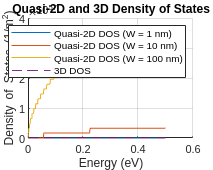

clc
clear
close all

% Constants
hbar = 1.054e-34; 
m = 9.107e-31;   
mo = 0.067 * m;   
W_values = [1, 10, 100] * 1e-9;  % Quantum well width in meters
W = W_values(1);
q = 1.6e-19;  

% Energy range in eV
E = linspace(0, 0.5, 500) * q;  % Convert eV to Joules
n = 1:20;

figure('Position', [100, 100, 1000, 800]); % Increase figure window size
hold on;
grid on;
xlabel('Energy (eV)');
ylabel('Density of States (1/m^2)');
title('Quasi-2D and 3D Density of States');

% Loop over W values to compute quasi-2D DOS
for i = 1:length(W_values)
    g_2D = zeros(size(E));
    
    % Compute subband energy levels
    E_n = ((hbar * pi * n / W_values(i)).^2) / (2 * mo);
    
    % Sum contributions of all subbands
    for j = 1:length(n)
        g_2D = g_2D + (m / (pi * hbar^2)) * (E > E_n(j));  % Step function contribution
    end
    
    % Plot DOS
    plot(E / q, g_2D / q, 'DisplayName', sprintf('Quasi-2D DOS (W = %.0f nm)', W_values(i) * 1e9));
end

% Compute 3D DOS
g_3D = (1 / (4 * pi^2)) * (2 * mo / (hbar^2))^(3/2) .* sqrt(E);
plot(E / q, g_3D * W / q, '--', 'DisplayName', '3D DOS');

legend('show');
hold off;

You can see that as the well width increases, the quasi-2D density of states starts to follow the $\propto\sqrt{E}$ relationship, similar to the 3D density of states. This following intuition, as the width increases, the third dimension is becoming less bounded, becoming almost 3D unbounded. When the width is small, it acts similar to the unbounded 2D density of states, where it doesn't depend on energy. If the 3D DOS was of the same magnitude, this would be clear, but I believe they are off by a factor of e4 because of the per volume to per area unit conversion.

**b)**

All degenerate wavevectors that have the same energy.

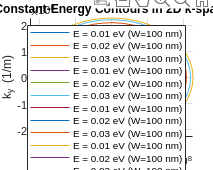

figure('Position', [100, 100, 1000, 800]); % Increase figure window size
hold on;
grid on;
xlabel('k_x (1/m)');
ylabel('k_y (1/m)');
title('Constant-Energy Contours in 2D k-space');

% Energy values to plot (in eV)
E_plot = [0.01, 0.02, 0.03] * q;
W_values = [1, 10, 100] * 1e-9;  % Quantum well width in meters
W = W_values(1);
n_values = 1:5;

for i = 1:length(W_values)

    for j = 1:length(n_values)
        E_n = (hbar^2 * (pi * n_values(j) / W_values(i))^2) / (2 * mo);
        
        for k = 1:length(E_plot)
            E = E_plot(k);
            if E > E_n  % Only plot if E > E_n
                k_mag = sqrt((2 * mo / hbar^2) * (E - E_n));
                theta = linspace(0, 2*pi, 50);
                kx = k_mag * cos(theta);
                ky = k_mag * sin(theta);
                plot(kx, ky, 'DisplayName', sprintf('E = %.2f eV (W=%.0f nm)', E/q, W_values(i)*1e9));
            end
        end
    end
end

legend('show');
hold off;

Not quite sure what the problems are with the legend, but not working correctly. You can still get the idea that in 2D, different energies have a grouping of degenerate k values.